## Cleaning

clear
clc

## Declare Variables

% Constant variables
altitude = 25500; % Desired altitude of 25000 m
payloadMass = 500; % Desired payload mass of 500 kg
FS = [1:1:100]'; % Self-selected number in range 1:5
Pgage = 10; % Gage pressure in Pa
gravity = 9.81; % Acceleration of gravity in m / s^2

% Variable variables (o_o )
    % Measurements based on information found in:
    % http://www.matweb.com/search/datasheet_print.aspx?matguid=bcd1ad1e1a7445aca5321d26f00bdf12
materialThickness = 3.81 * 10^-5; % Balloon material thickness in m
YS = 15.5 * 10^6; % Yield strength of balloon material in Pa
materialDensity = 924; % Density of material in kg / m^3
gasConst = 8.31447e3; % Universal gas constant in J / kg*K
gasConstHe = 2.0769e3; % Gas constant of Helium in J / kg*K

% Create table for data
data = table(FS, 'VariableNames', {'FactorSafety'});

## Declare equations

% Calculate sphere volume given radius
sphereVol = @(r) (4/3) * pi * (r.^3)

sphereVol = function_handle with value:
    @(r)(4/3)*pi*(r.^3)



% Calculate yield strength given factor of safety, gage pressure, radius,
% and thickness
yieldStrength = @(F_S, Pgage, r, t) (F_S .* (Pgage * r)) ./ (2 * t)

yieldStrength = function_handle with value:
    @(F_S,Pgage,r,t)(F_S.*(Pgage*r))./(2*t)



% Calculate stress given gage pressure, radius, and thickness
stress = @(Pgage, r, t) (Pgage * r) / (2 * t)

stress = function_handle with value:
    @(Pgage,r,t)(Pgage*r)/(2*t)



% Calculate radius given density of air, pressure of air, factor of safety,
% yield strength of material, and temperature
radius = @(denAir, pressureAir, FS, YS, temp) abs(payloadMass ./ ( ((4/3) * denAir * pi) - (((materialDensity * 2 * pi * Pgage) .* FS) ./ YS) - ( ((pressureAir * 4 * pi) / ((3 * gasConstHe) .* temp))) )) .^ (1/3)

radius = function_handle with value:
    @(denAir,pressureAir,FS,YS,temp)abs(payloadMass./(((4/3)*denAir*pi)-(((materialDensity*2*pi*Pgage).*FS)./YS)-(((pressureAir*4*pi)/((3*gasConstHe).*temp))))).^(1/3)



% Calculate buoyancy force given fluid density, gravity, and volume
buoyancy = @(density, volume) density * gravity * volume

buoyancy = function_handle with value:
    @(density,volume)density*gravity*volume



% Calculate force of gravity given mass
weight = @(mass) mass * gravity

weight = function_handle with value:
    @(mass)mass*gravity



thick = @(FS, radius) (FS .* Pgage .* radius) ./ (2 .* YS);

## Calculate approximate balloon radius

bisonTopSpeed = 35 * 0.44704 % m/s

bisonTopSpeed = 15.6464

## Begin calculations

% Find atmospheric conditions based on 1976 model
[temp, ~, pressure, densityAir] = atmoscoesa(altitude)

temp = 222.1500

pressure = 2.3250e+03

densityAir = 0.0365


% Find radius of balloon 
data.balloonRadius = radius(densityAir, pressure, data.FactorSafety, YS, temp); % Radius in m

% Find volume of balloon
data.balloonVolume = sphereVol(data.balloonRadius); % Volume in m^3

% Find buoyancy force
data.forceBuoyancy = buoyancy(densityAir, data.balloonVolume); % Buoyancy force in N

% Find force of gravity (weight of balloon)
data.thickness = thick(data.FactorSafety, data.balloonRadius); % Thickness in m
data.amtBalloonMaterial = data.balloonVolume - sphereVol(data.balloonRadius - data.thickness); % m^3
data.massHeFBE = (densityAir * data.balloonVolume) - payloadMass - (materialDensity * data.amtBalloonMaterial); % Mass of He in kg
data.totalMass = (data.amtBalloonMaterial * materialDensity) + payloadMass + data.massHeFBE; % Total mass of the system in kg
data.forceGravity = weight(data.totalMass); % Force of gravity of the system in N --> should be equal to the force of buoyancy

% Find mass of He from PV=nRT equation
massHePVNRT = (pressure .* data.balloonVolume) ./ (gasConst * temp);

## Find effects of temperature change

% Given values
alpha_sb = 0.6;
epsilon_b = 0.8;
alpha_eb = epsilon_b;
q_sun = 1353; % W / m^2
q_earth = 237; % W / m^2

% Calculate max and min temperatures
data.Q_dot_solar = (alpha_sb * q_sun * pi) .* (data.balloonRadius .^ 2); % Change in thermal energy of the sun in W
data.Q_dot_earth = (alpha_eb * q_earth * pi) .* (data.balloonRadius .^ 2); % Change in  thermal energy of the earth in W
Tday = ( (data.Q_dot_solar + data.Q_dot_earth) ./ ( (4 * pi * 5.67e-8 * .8) * (data.balloonRadius .^ 2) ) ) .^ (1/4); % Max temperature in K
Tnight = ( data.Q_dot_earth ./ ( (4 * pi * 5.67e-8 * .8) * (data.balloonRadius .^ 2) ) ) .^ (1/4); % Min temperature in K
Tday = Tday(1)

Tday = 272.5641

Tnight = Tnight(1)

Tnight = 179.7945


% Calculate the density of helium at different temperatures
denHeBase = (pressure + Pgage) / (gasConstHe * temp) % Density of helium at conditions at 25 km

denHeBase = 0.0051

denHeNight = (pressure + Pgage) / (gasConstHe * Tnight) % Density of helium at night temp

denHeNight = 0.0063

denHeDay = (pressure + Pgage) / (gasConstHe * Tday) % Density of helium at day temp

denHeDay = 0.0041


% Calculate the new volumes corresponding to the new densities
volHeBase = (data.massHeFBE ./ denHeBase); % Volume in m^3
data.volHeNight = (data.massHeFBE ./ denHeNight); % Volume in m^3
data.volHeDay = (data.massHeFBE ./ denHeDay); % Volume in m^3

% Calculate the density of surrounding air at new temperatures
denAirBase = data.totalMass ./ volHeBase; % Density in kg/m^3
denAirNight = data.totalMass ./ data.volHeNight; % Density in kg/m^3
denAirDay = data.totalMass ./ data.volHeDay; % Density in kg/m^3
denAirBase = denAirBase(1)

denAirBase = 0.0366

denAirNight = denAirNight(1)

denAirNight = 0.0452

denAirDay = denAirDay(1)

denAirDay = 0.0298


% Calculate altitude corresponding to air densities
altAirBase = densityalt(denAirBase)

altAirBase = 2.5473e+04

altAirNight = densityalt(denAirNight)

altAirNight = 2.4141e+04

altAirDay = densityalt(denAirDay)

altAirDay = 2.6769e+04

## Calculate amount of ballast necessary to achieve flight parameters

% Find atmospheric properties at high and low altitudes
    % Need to take into account pressure and density variations at the
    % altitudes above and below the mean altitude
[~, ~, pressureMax, densityAirMax] = atmoscoesa(altitude + 1000) % Find atmospheric information at max altitude

pressureMax = 1.9943e+03

densityAirMax = 0.0311

[~, ~, pressureMin, densityAirMin] = atmoscoesa(altitude - 1000) % Find atmospheric information at min altitude

pressureMin = 2.7124e+03

densityAirMin = 0.0427


% Calculate amount of ballast necessary for neutral buoyancy within
% altitude limit
data.massBallastDay = densityAirMax .* data.volHeDay - data.massHeFBE - data.amtBalloonMaterial - payloadMass; % Mass in kg

% Check that balloon with extra mass will be within range

maxAltCheck =     0.0319
    0.0326
    0.0333
    0.0341
    0.0348
    0.0355
    0.0363
    0.0370
    0.0377
    0.0384



data

data = 100×14 table
    FactorSafety    balloonRadius    balloonVolume    forceBuoyancy    thickness     amtBalloonMaterial    massHeFBE    totalMass    forceGravity    Q_dot_solar    Q_dot_earth    volHeNight    volHeDay    massBallastDay
    ____________    _____________    _____________    _____________    __________    __________________    _________    _________    ____________    ___________    ___________    __________    ________    ______________

          1            15.754            16379           5858.4

## Graphs of features vs Factor of Safety

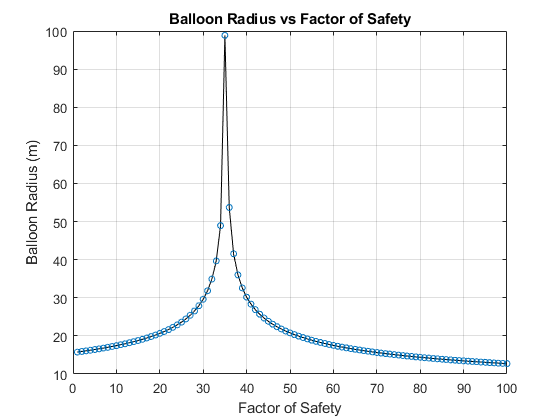

% Plotted so far:
% - Balloon radius
% - Balloon volume
% - Force of buoyancy
% - Thickness
% - Mass of helium
% - Ballast mass

% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.balloonRadius, 'k')
hold on
scatter(data.FactorSafety, data.balloonRadius, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Balloon Radius vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Radius (m)")

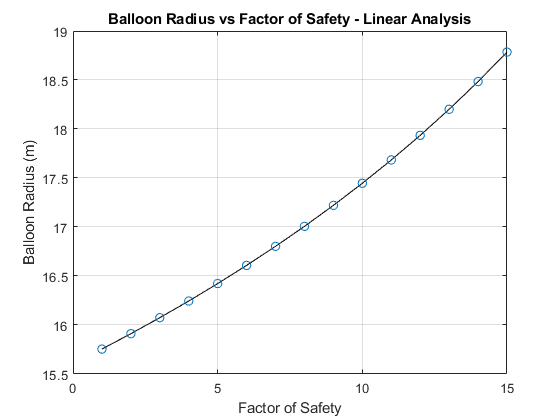


% Linear analysis
plot(data.FactorSafety(1:15), data.balloonRadius(1:15), 'k')
hold on
scatter(data.FactorSafety(1:15), data.balloonRadius(1:15), 40, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Balloon Radius vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Balloon Radius (m)")

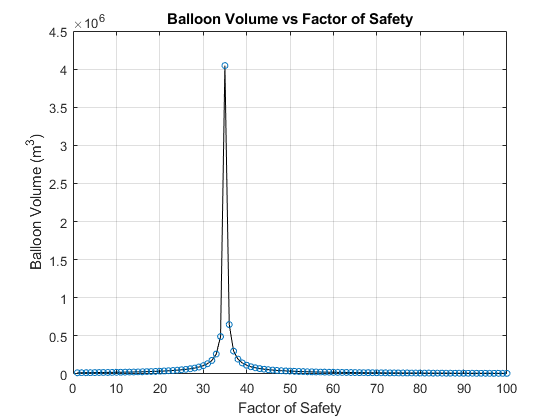


% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.balloonVolume, 'k')
hold on
scatter(data.FactorSafety, data.balloonVolume, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Balloon Volume vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Volume (m^3)")

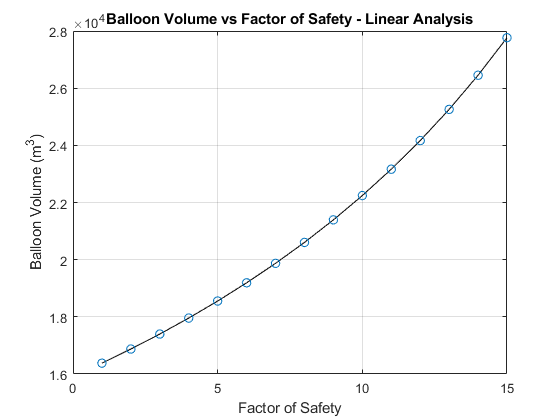


% Linear analysis
plot(data.FactorSafety(1:15), data.balloonVolume(1:15), 'k')
hold on
scatter(data.FactorSafety(1:15), data.balloonVolume(1:15), 40, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Balloon Volume vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Balloon Volume (m^3)")

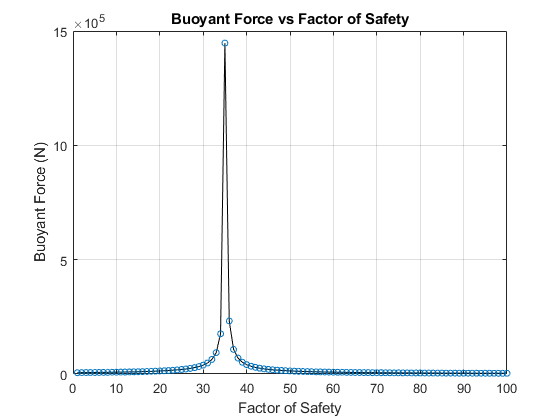


% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.forceBuoyancy, 'k')
hold on
scatter(data.FactorSafety, data.forceBuoyancy, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Buoyant Force vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Buoyant Force (N)")

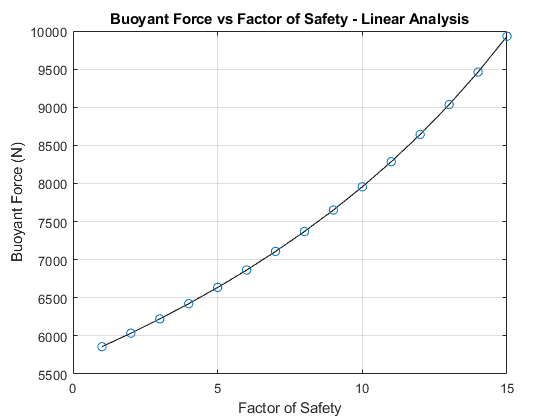


% Linear analysis
plot(data.FactorSafety(1:15), data.forceBuoyancy(1:15), 'k')
hold on
scatter(data.FactorSafety(1:15), data.forceBuoyancy(1:15), 40, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Buoyant Force vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Buoyant Force (N)")

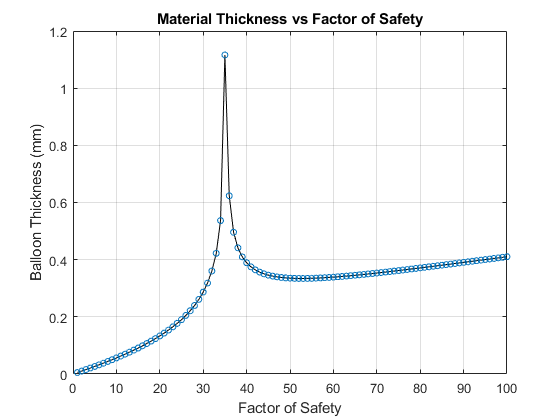


% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.thickness .* 1000, 'k')
hold on
scatter(data.FactorSafety, data.thickness .* 1000, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Material Thickness vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Thickness (mm)")

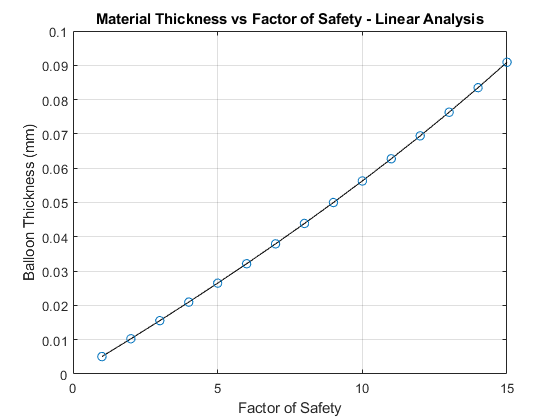


% Linear analysis
plot(data.FactorSafety(1:15), data.thickness(1:15) .* 1000, 'k')
hold on
scatter(data.FactorSafety(1:15), data.thickness(1:15) .* 1000, 40, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Material Thickness vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Balloon Thickness (mm)")

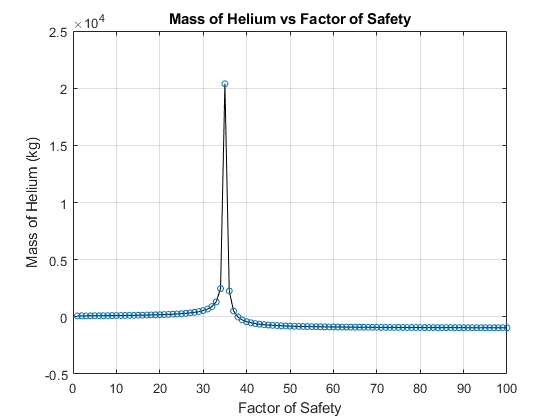


% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.massHeFBE, 'k')
hold on
scatter(data.FactorSafety, data.massHeFBE, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Mass of Helium vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Mass of Helium (kg)")

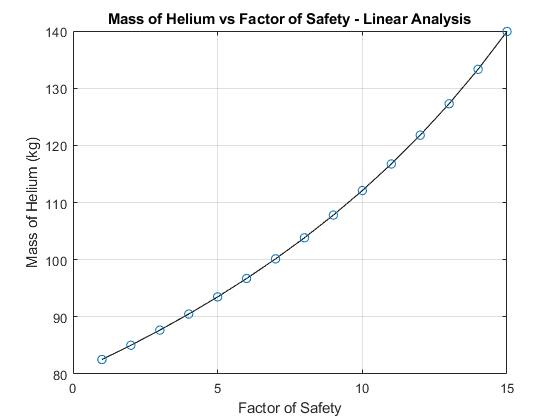


% Linear analysis
plot(data.FactorSafety(1:15), data.massHeFBE(1:15), 'k')
hold on
scatter(data.FactorSafety(1:15), data.massHeFBE(1:15), 40, "MarkerEdgeColor", '#0072BD')
hold off
grid on
title("Mass of Helium vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Mass of Helium (kg)")

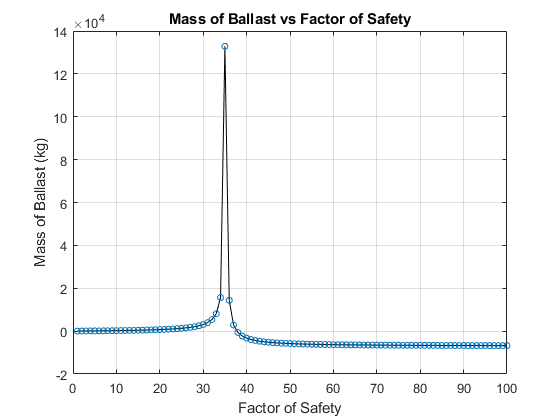


% ------------------------------------------------------------------------------------------ %

plot(data.FactorSafety, data.massBallastDay, 'k')
hold on
scatter(data.FactorSafety, data.massBallastDay, 20, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Mass of Ballast vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Mass of Ballast (kg)")

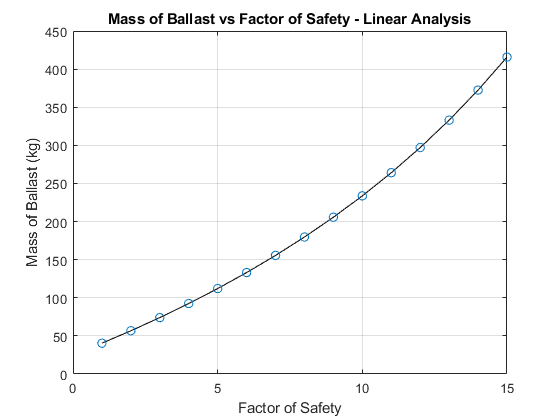



% Linear analysis
plot(data.FactorSafety(1:15), data.massBallastDay(1:15), 'k')
hold on
scatter(data.FactorSafety(1:15), data.massBallastDay(1:15), 40, 'MarkerEdgeColor', '#0072BD')
hold off
grid on
title("Mass of Ballast vs Factor of Safety - Linear Analysis")
xlabel("Factor of Safety")
ylabel("Mass of Ballast (kg)")

% [https://www.mathworks.com/matlabcentral/fileexchange/28135-standard-atmosphere-functions](https://www.mathworks.com/matlabcentral/fileexchange/28135-standard-atmosphere-functions) 

function h = densityalt(rho,varargin)
% DENSITYALT  Returns altitude corresponding to the given array of air densities
%   in the standard or non-standard atmosphere.
%
%   H = DENSITYALT(RHO) returns altitude, h, as a function of air density, rho.
% 
%   The input RHO can be followed by parameter/value pairs for further control
%   of DENSITYALT. Possible parameters are:
%     inputUnits     - String for units of input RHO, either kg/m³ or slug/ft³.
%                      [{SI}|kg/m3|kg/m^3  |  US|slug/ft3|slug/ft^3]
%     outputUnits    - String for units of output H, either meters or feet.
%                      [{SI}|m|meters  |  US|ft|feet]
%     atmosphereFunc - String determining atmosphere function to be used.
%                      [{atmos}|tropos|atmosisa|atmoscoesa|atmosnonstd]
%     atmosphereArgs - Cell array of additional arguments to pass to 
%                      atmosphereFunction after the density input (e.g. for non-
%                      standard atmospheres).
%     method         - Method used for either searching for or interpolating a
%                      solution (the equations that define the standard 
%                      atmosphere cannot be inverted in terms of density).
%                      Search: [fzero | bisection] (fzero only for scalar case)
%                      Interpolate: any method accepted by interp1.
%                      Default method is 'pchip' for interpolation.
%     options        - Options used for fzero or bisection methods.
%     hMin           - For search: lower search interval bound in meters. 
%                      For interpolation: start of generated interpolation grid.
%                      Default hMin = 0.
%     hMax           - For search: upper search interval bound in meters. 
%                      For interpolation: end of generated interpolation grid.
%                      Default hMax = 86000.
%     spacing        - Spacing of of interpolation grid in meters. 
%                      Default spacing = 50.
% 
%   If the input RHO is a DimVar, inputUnits and outputUnits will be ignored and
%   the output will be a DimVar.
%
%   DENSITYALT is valid for the entire standard atmosphere up through the
%   mesopause (86 km height). It assumes that all that is known is air
%   density. If pressure or temperature and density are known, there exist
%   more straightforward methods for calculating density altitude:
%       P = rho*R*T; h = h0 * (1 - P^0.190284), where P is in atmospheres and 
%           h0 = 145366.45 ft or 44307.694 m.
%       (http://www.srh.noaa.gov/images/epz/wxcalc/pressureAltitude.pdf)
% 
%   Example: Plot altitude as a function of air density for a cold (-15°C),
%   standard, and hot (+15°C) day (leverages vectorization of bisection).
%       rho = 1.225:-0.01:0.025; % kg/m^3
%       tempOffset = [-15 0 15]; % °C
%       [rho, tempOffset] = meshgrid(rho,tempOffset);
%       h = densityalt(rho,'method','bisection','outputUnits','ft',...
%               'atmosphereArgs',{tempOffset},'hMin',-5000);
%       plot(rho',h'/1000);
%       xlabel('Air density (kg/m^3)'); ylabel('Altitude (kft)'); grid on
%       legend('Cold','Standard','Hot')
% 
%   See also ATMOSISA, ATMOSNONSTD, ATMOSCOESA, INTERP1, FZERO, 
%     BISECTION - http://www.mathworks.com/matlabcentral/fileexchange/28150,
%     ATMOS     - http://www.mathworks.com/matlabcentral/fileexchange/28135,
%     U, UNITS  - http://www.mathworks.com/matlabcentral/fileexchange/38977.
%
%   H = DENSITYALT(RHO,Param1,Val1,Param2,Val2,...)
%   Copyright 2012-2013, 2015 Sky Sartorius
%   Author contact: mathworks.com/matlabcentral/fileexchange/authors/101715
% The 'pchip' method is smooth, preserves the shape, and has very tiny errors
% for most of the domain. However, the errors around the discontinuous
% transisions between atmospheres (e.g. between troposphere and tropopause) can
% be on the order of 1/100th of the spacing of given H. For spacing of 50 m,
% errors are never more than 813 mm. The absolute errors at these
% discontinuities are an order of magnitude lower for the 'linear' method but
% the error is present across the entire domain.
%% Parse inputs:
p = inputParser;
fName = 'densityalt';
p.FunctionName = fName;
p.addRequired('rho',@(x) validateattributes(x,{'numeric','DimVar'},...
    {'positive'},'','density, rho,'));
% Ignored if input is DimVar:
p.addParameter('inputUnits','SI');
p.addParameter('outputUnits','SI');
p.addParameter('atmosphereFunction','atmos');
p.addParameter('atmosphereArgs',{},@iscell);
p.addParameter('method','pchip'); 
% Possibilities are exact matches of 'fzero' or 'bisection', or an interp1
% method. Validation by interp1.
p.addParameter('hMin',0,@(x) validateattributes(x,{'numeric'},...
    {'scalar','finite','real'},'','altitude minimum h (m)'));
p.addParameter('hMax',86000,@(x) validateattributes(x,{'numeric'},...
    {'scalar','finite','real'},'','altitude maximum h (m)'));
% Used only with fzero/bisection search method:
p.addParameter('options',{})
% Used only with an interp method:
p.addParameter('spacing',50,@(x) validateattributes(x,{'numeric'},...
    {'positive','scalar','finite','real'},'','altitude grid spacing (m)'));
parse(p,rho,varargin{:});
i = p.Results;
rho = i.rho;
if ~iscell(i.options)
    i.options = {i.options};
end
% Validate inputs strings:
i.inputUnits = validatestring(i.inputUnits,...
    {'SI','kg/m3','kg/m^3','US','slug/ft3','slug/ft^3'},fName,'inputUnits');
i.outputUnits = validatestring(i.outputUnits,...
    {'SI','m','meters','US','ft','feet'},fName,'outputUnits');
i.atmosphereFuntion = validatestring(i.atmosphereFunction,...
    {'atmos','tropos','atmosisa','atmoscoesa','atmosnonstd'},...
    fName,'atmosphereFunction');
%% Process input density and return density in units of kg/m^3:
dimVarOut = false; % Flag to convert output to a DimVar.
if isa(rho,'DimVar')
    rho = rho/(u.kg/u.m^3);
    dimVarOut = true; 
elseif any(strcmpi(i.inputUnits,{'US','slug/ft3','slug/ft^3'}))
    % Convert from imperial units.
    rho = rho * 515.3788183931961;
end
% Otherwise, input rho is already in kg/m^3.
%% Build atmosphere model:
% Build an atmosphere function that takes only altitude (in meters) as input and
% returns density (in kg/m^3) as the first and only output.
function rho = myAtmo(h)
    switch i.atmosphereFunction
        case {'atmos' 'tropos'}
            rho = feval(i.atmosphereFunction,h,i.atmosphereArgs{:});
        otherwise
            % Other functions return density as the fourth output.
            [~,~,~,rho] = feval(i.atmosphereFunction,h,i.atmosphereArgs{:});
    end
end
%% Find the altitude:
% Switch between search and interpolation methods:
switch i.method
    case 'fzero'
        h = fzero(@(h) rho-myAtmo(h),[i.hMin,i.hMax],i.options{:});
        
    case 'bisection'
        h = bisection(@myAtmo,i.hMin,i.hMax,rho,i.options{:});
        
    otherwise % interp1
        H = (i.hMin:i.spacing:i.hMax)';
        RHO = myAtmo(H);
        h = interp1(RHO,H,rho,i.method);
end
%% Process output altitude from meters into desired units:
if dimVarOut
    h = h*u.m;
elseif any(strcmpi(i.outputUnits,{'US','ft','feet'})) 
    % Convert to imperial units if necessary.
    h = h / 0.3048;
end
% Otherwise, output h is already in meters.
end

function varargout = atmos(h,varargin)
%  ATMOS  Find gas properties in the 1976 Standard Atmosphere.
%   [rho,a,T,P,nu,z,sigma] = ATMOS(h,varargin)
%
%   ATMOS by itself gives atmospheric properties at sea level on a standard day.
%
%   ATMOS(h) returns the properties of the 1976 Standard Atmosphere at
%   geopotential altitude h, where h is a scalar, vector, matrix, or ND array.
% 
%   The input h can be followed by parameter/value pairs for further control of
%   ATMOS. Possible parameters are:
%     tOffset      - Returns properties when the temperature is tOffset degrees 
%                    above or below standand conditions. h and tOffset must be
%                    the same size or else one must be a scalar. Default is no
%                    offset. Note that this is an offset, so when converting
%                    between Celsius and Fahrenheit, use only the scaling factor
%                    (dC/dF = dK/dR = 5/9).
%     tAbsolute    - Similar to tOffest, but an absolute air temperature is 
%                    provided (°K or °R) instead of an offset from the standard 
%                    temperature. Supersedes tOffset if both are provided.
%     altType      - Specify type of input altitude, either 'geopotential' (h)
%                    or 'geometric' (z). Default altType = 'geopotential'.
%     structOutput - When set, ATMOS produces a single struct output with fields
%                    rho, a, T, P, nu, and either z or h (whichever complements
%                    input altType). Default structOutput = false.
%     units        - String for units of inputs and outpus, either 'SI'
%                    (default) or 'US'. This is ignored if the provided input h
%                    is a DimVar, in which case all outputs are also DimVars and
%                    expected tOffset is either a DimVar or in °C/°K.
%                                 Description:         SI:           US:
%                     Input:      --------------       -----         -----
%                       h | z     Altitude or height   m             ft
%                       tOffset   Temp. offset         °C/°K         °F/°R
%                     Output:     --------------       -----         -----
%                       rho       Density              kg/m^3        slug/ft^3
%                       a         Speed of sound       m/s           ft/s
%                       T         Temperature          °K            °R
%                       P         Pressure             Pa            lbf/ft^2
%                       nu        Kinem. viscosity     m^2/s         ft^2/s
%                       z | h     Height or altitude   m             ft
%                       sigma     Density ratio        -             -
%
%   ATMOS returns properties the same size as h and/or tOffset (P does not vary
%   with temperature offset and is always the size of h).
%
%   Example 1: Find atmospheric properties at every 100 m of geometric height
%   for an off-standard atmosphere with temperature offset varying +/- 25°C
%   sinusoidally with a period of 4 km.
%       z = 0:100:86000;
%       [rho,a,T,P,nu,h,sigma] = atmos(z,'tOffset',25*sin(pi*z/2000),...
%                                        'altType','geometric');
%       semilogx(sigma,h/1000)
%       title('Density variation with sinusoidal off-standard atmosphere')
%       xlabel('Density ratio, \sigma'); ylabel('Geopotential altitude (km)')
%
%   Example 2: Create tables of atmospheric properties up to 30,000 ft for a
%   cold (-20°C), standard, and hot (+20°C) day with columns
%   [h(ft) z(ft) rho(slug/ft³) sigma a(ft/s) T(R) P(psf) µ(slug/ft-s) nu(ft²/s)]
%   leveraging n-dimensional array capability.
%       [~,h,dT] = meshgrid(0,-5000:1000:30000,[-20 0 20]);
%       [rho,a,T,P,nu,z,sigma] = atmos(h,'tOffset',dT*9/5,'units','US');
%       t = [h z rho sigma a T P nu.*rho nu];
%       format short e
%       varNames = {'h' 'z' 'rho' 'sigma' 'a' 'T' 'P' 'mu' 'nu'};
%       ColdTable       = array2table(t(:,:,1),'VariableNames',varNames)
%       StandardTable   = array2table(t(:,:,2),'VariableNames',varNames)
%       HotTable        = array2table(t(:,:,3),'VariableNames',varNames)
%
%   Example 3: Use the unit consistency enforced by the DimVar class to find the
%   SI dynamic pressure, Mach number, Reynolds number, and stagnation
%   temperature of an aircraft flying at flight level FL500 (50000 ft) with
%   speed 500 knots and characteristic length of 80 inches.
%       V = 500*u.kts; c = 80*u.in;
%       o = atmos(50*u.kft,'structOutput',true);
%       Dyn_Press = 1/2*o.rho*V^2;
%       M = V/o.a;
%       Re = V*c/o.nu;
%       T0 = o.T*(1+(1.4-1)/2*M^2);
%
%   This model is not recommended for use at altitudes above 86 km geometric
%   height (84852 m / 278386 ft geopotential) but will attempt to extrapolate
%   above 86 km (with a lapse rate of 0°/km) and below 0.
%
%   See also ATMOSISA, ATMOSNONSTD, TROPOS,
%     DENSITYALT - http://www.mathworks.com/matlabcentral/fileexchange/39325,
%     UNITS      - http://www.mathworks.com/matlabcentral/fileexchange/38977.
%
%   [rho,a,T,P,nu,z,sigma] = ATMOS(h,varargin)
%   Copyright 2015 Sky Sartorius
%   www.mathworks.com/matlabcentral/fileexchange/authors/101715
% 
%   References: ESDU 77022; www.pdas.com/atmos.html
%% User-customizable defaults:
defaultUnits = 'SI'; % Alternate: 'US'
defaultStructOutput = false;
%% Parse inputs:
if nargin == 0
    h = 0;
end
if nargin <= 1 && ~nnz(h)
    % Quick return of sea level conditions.
    rho = 1.225;
    a = 340.2940;
    temp = 288.15;
    press = 101325;
    kvisc = 1.4607186e-05;
    ZorH = 0;
    if isa(h,'DimVar')
        rho = rho*u.kg/(u.m^3);
        if nargout == 1
            varargout = {rho};
            return
        end
        a = a*u.m/u.s;
        temp = temp*u.K;
        press = press*u.Pa;
        kvisc = kvisc*u.m^2/u.s;
        ZorH = ZorH*u.m;
    end
    varargout = {rho,a,temp,press,kvisc,ZorH,1};
    return
end
    
% validateattributes(h,{'DimVar' 'numeric'},{'finite' 'real'});
p = inputParser;
addParameter(p,'tOffset',0);
addParameter(p,'tAbsolute',[]);
addParameter(p,'units',defaultUnits);
addParameter(p,'altType','geopotential');
addParameter(p,'structOutput',defaultStructOutput);
parse(p,varargin{:});
tOffset = p.Results.tOffset; 
tAbsolute = p.Results.tAbsolute;
if strcmpi(p.Results.units,'SI')
    convertUnits = false;
elseif strcmpi(p.Results.units,'US')
    convertUnits = true;
    % Flag if I need to convert to/from SI.
else
    error('Invalid units. Expected: ''SI'' or ''US''.')
end    
if strcmpi(p.Results.altType,'geopotential')
    geomFlag = false;
elseif strcmpi(p.Results.altType,'geometric')
    geomFlag = true;
    % Flag specifying z provided as input.
else
    error('Invalid altType. Expected: ''geopotential'' or ''geometric''.')
end
structOutput = p.Results.structOutput;
%% Deal with different input types:
dimVarOut = false;
if isa(h,'DimVar')
    h = h/u.m;
    dimVarOut = true;
    convertUnits = false; % Trumps specified units.
end
if isa(tOffset,'DimVar')
    tOffset = tOffset/u.K;
    % It is allowed to mix DimVar h_in and double tOffset (or reverse). 
end
if isa(tAbsolute,'DimVar')
    tAbsolute = tAbsolute/u.K;
end
if convertUnits
    h = h * 0.3048;
    tOffset   = tOffset   * 5/9;
    tAbsolute = tAbsolute * 5/9;
end
%% Constants, etc.:
%  Lapse rate Base Temp       Base Geop. Alt    Base Pressure
%   Ki (°C/m) Ti (°K)         Hi (m)            P (Pa)
D =[-0.0065   288.15          0                 101325            % Troposphere
    0         216.65          11000             22632.04059693474 % Tropopause
    0.001     216.65          20000             5474.877660660026 % Stratosph. 1
    0.0028    228.65          32000             868.0158377493657 % Stratosph. 2
    0         270.65          47000             110.9057845539146 % Stratopause
    -0.0028   270.65          51000             66.938535373039073% Mesosphere 1
    -0.002    214.65          71000             3.956392754582863 % Mesosphere 2
    0         186.94590831019 84852.04584490575 .373377242877530];% Mesopause
% Constants:
rho0 = 1.225;   % Sea level density, kg/m^3
gamma = 1.4;
g0 = 9.80665;   %m/sec^2
RE = 6356766;   %Radius of the Earth, m
Bs = 1.458e-6;  %N-s/m2 K1/2
S = 110.4;      %K
K = D(:,1);	%°K/m
T = D(:,2);	%°K
H = D(:,3);	%m
P = D(:,4);	%Pa
R = P(1)/T(1)/rho0; %N-m/kg-K
% Ref:
%   287.05287 N-m/kg-K: value from ESDU 77022
%   287.0531 N-m/kg-K:  value used by MATLAB aerospace toolbox ATMOSISA
%% Convert from geometric altitude to geopotental altitude, if necessary.
if geomFlag
    hGeop = (RE*h) ./ (RE + h);
else
    hGeop = h;
end
%% Calculate temperature and pressure:
% Pre-allocate.
temp = zeros(size(h));
press = temp;
nSpheres = size(D,1);
for i = 1:nSpheres
    % Put inputs into the right altitude bins:
    if i == 1 % Extrapolate below first defined atmosphere.
        n = hGeop <= H(2);
    elseif i == nSpheres % Capture all above top of defined atmosphere.
        n = hGeop > H(nSpheres);
    else 
        n = hGeop <= H(i+1) & hGeop > H(i);
    end
    
    
    if K(i) == 0 % No temperature lapse.
        temp(n) = T(i);
        press(n) = P(i) * exp(-g0*(hGeop(n)-H(i))/(T(i)*R));
    else
        TonTi = 1 + K(i)*(hGeop(n) - H(i))/T(i);
        temp(n) = TonTi*T(i); 
        press(n) = P(i) * TonTi.^(-g0/(K(i)*R)); % Undefined for K = 0.
    end
end
%% Switch between using standard temp and provided absolute temp.
if isempty(tAbsolute)
    % No absolute temperature provided - use tOffset.
    temp = temp + tOffset;
else
    temp = tAbsolute;
end
%% Populate the rest of the parameters:
rho = press./temp/R;
sigma = rho/rho0;
a = sqrt(gamma * R * temp);
kvisc = (Bs * temp.^1.5 ./ (temp + S)) ./ rho; %m2/s
if geomFlag % Geometric in, ZorH is geopotential altitude (H)
    ZorH = hGeop;
else % Geop in, find Z
    ZorH = RE*hGeop./(RE-hGeop);
end
%% Process outputs:
if dimVarOut
    rho = rho*u.kg/(u.m^3);
    a = a*u.m/u.s;
    temp = temp*u.K;
    press = press*u.Pa;
    kvisc = kvisc*u.m^2/u.s;
    ZorH = ZorH*u.m;
elseif convertUnits
    rho = rho / 515.3788;
    a = a / 0.3048;
    temp = temp * 1.8;
    press = press / 47.88026;
    kvisc = kvisc / 0.09290304;
    ZorH = ZorH / 0.3048;
end
varargout = {rho,a,temp,press,kvisc,ZorH,sigma};
if structOutput
    if geomFlag
        ZorHname = 'h';
    else
        ZorHname = 'z';
    end
    names = {'rho' 'a' 'T' 'P' 'nu' ZorHname 'sigma'};
    varargout = {cell2struct(varargout,names,2)};
end
end